clc, clear all, close all;
format longG;

S2 = S_kruh(25);
sigma_a_a = 1.6*napeti(70000-50000-110000,S2)

sigma_a_a =          -293.354391106981


sigma_a = round(sigma_a_a,0)

sigma_a =   -293



S1 = S_kruh(18);
tah = napeti(70000,S1);
round(tah)

ans =    275


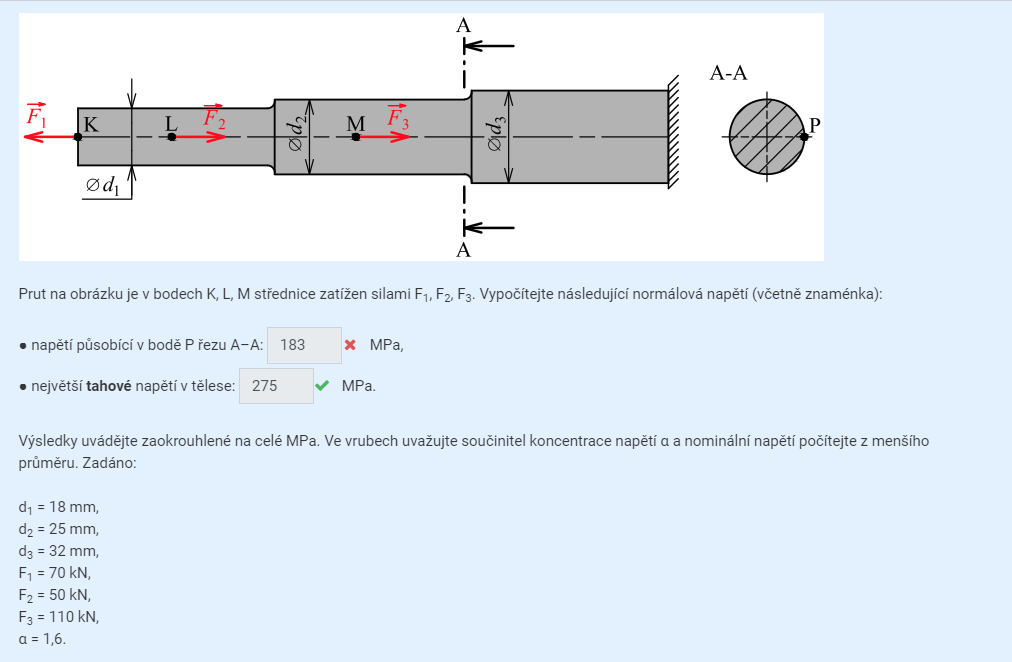

% jednotlive usekuy prutu dle N 
prumery = [18,18,25,25];
N = [70000,20000,20000,-90000];

S = arrayfun(@S_kruh,prumery)

S =           254.469004940773          254.469004940773          490.873852123405          490.873852123405


Sigma = arrayfun(@napeti,N,S)

Sigma =           275.082617689696          78.5950336256273          40.7436654315252         -183.346494441863


%nejvetsi_tahove = round(max(Sigma),0)

alfa = 1.6;
%napeti_a_a = round(alfa*Sigma(4),0)

Koncentrovane = alfa*[Sigma(2),Sigma(4)];
napeti_a_a = round(Koncentrovane(2),0)

napeti_a_a =   -293


nejvetsi_tahove = round(max([Sigma,Koncentrovane]),0)

nejvetsi_tahove =    275


Support funkce 

function S = S_obdelnik(b,h)
S = h*b;
end

function S = S_kruh(d)
S = (pi*(d^2))/(4);
end

function sigma = napeti(N,S)
sigma = (N)/(S);
end